Cargando datos de entrada y deseados ...
Los datos cargados tienen:
	- Número de entradas = 2
	- Número de salidas = 1
	- Número de datos = 150

Los datos se dividen en:
	- Datos de entrenamiento = 150
	- Datos de validación = 150
	- Datos de prueba = 150
Entrenando la red neuronal ...
Graficando errores cuadráticos medio ...


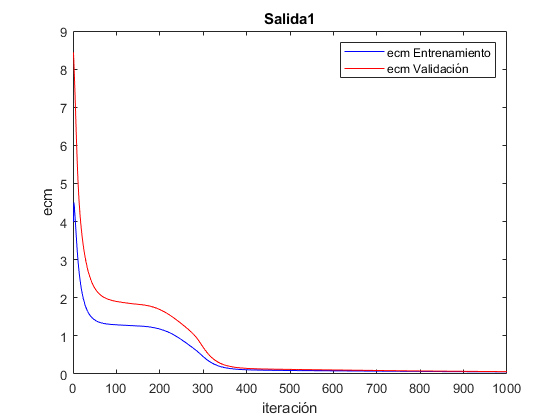

ECM Para prueba es: 0.053084 


%  ojo, aveces no toma un minimo local bueno
load TRAMOS.mat

Bias=1;
alfa = 0.01;
nit=1000;
% apartir de 4 esta descente, depende del
% nivel de sobreajuste (en validacion) que se quiera
no=4;
% en este caso nit puede ser hasta 200
% y el alfa puede incrementar un poco,

run Carga_Datos_Multicapa2.m

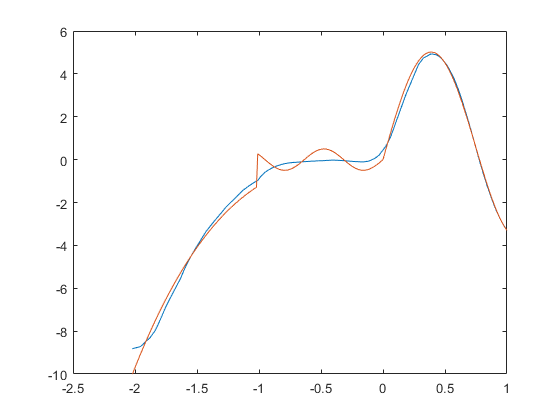


% no es necesario normalizar, ya que rangos
% de valores son pequenos

% resultado con datos de entrenamiento
plot(tnEntradas(end,:),yrkTn)
hold on
plot(entradas(end,:),deseados);
hold off

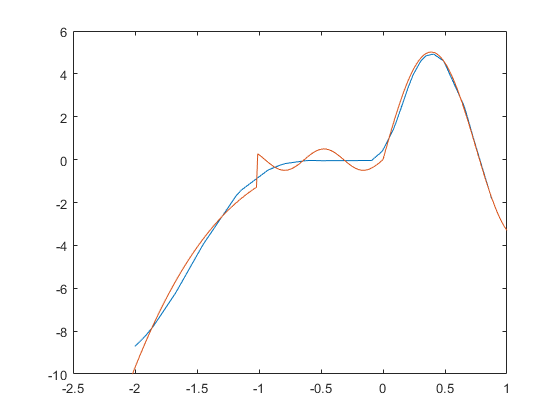

% resultado con datos de validacion
plot(vEntradas(end,:),yrkV)
hold on
plot(entradas(end,:),deseados);
hold off

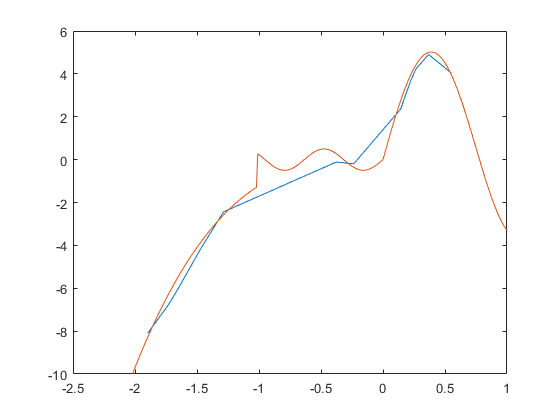

% resultados con datos de testeo
plot(tEntradas(end,:),yrkTest)
hold on
plot(entradas(end,:),deseados);
hold off

Decisiones para elección de parámetros

1, it) siempre y cuando los errores sean asintoticos horizontalmente en ML, el numero de iteraciones está bien

2, alfa) dependiendo de la grafica de ecm, la rapidez con la que deciende indica la sensibilidad del alfa. si no desciende está mal

3, no)(supuesto/sospecha) dada la complejidad de las funciones (dificil describir con pocos terminos en series de taylor), se necesitan muchas neuronas ocultas (estas teóricamente serán los terminos de las series de potencia)

4, bias) desconosco cuando usar y cuando no con capas ocultas, pero suele utilizarse cuando hay offset en los datos.

Observaciones:

al final de cuenta (creo), la red neuronal empleada es con 1 capa oculta activadas con simoidea (clasificacion), y con capa de salida activada con adaline.

al final, la capa oculta se encarga de clasificar o elegir  las entradas representativas para cada tramo, y la capa de salida toma esos parametros para obtener ecuaciones de recta (sumatoria con activacion lineal).